G1= zpk([-5.897],[-5.934 -2.242],0.443, 'InputDelay',0.534)

G1 =
 
                   0.443 (s+5.897)
  exp(-0.53*s) * -------------------
                 (s+5.934) (s+2.242)
 
Continuous-time zero/pole/gain model.



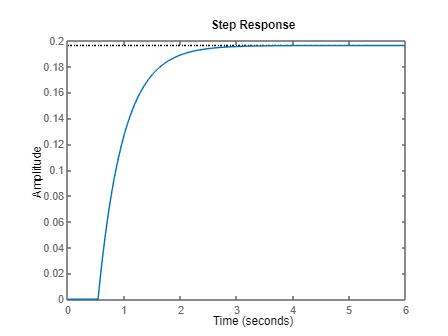

clf
step(G1,6)

tiempofinal=2.55;
[y1, t1] = step(G1,tiempofinal);
inicio = find(y>0,1);
yvalores1= y1(inicio:end);
tvalores1= t1(inicio:end);
k= y(end) - y(1)

k = 0.1964

k1=0.2;
[p1,s1] = polyfit(tvalores1,log(1-yvalores1/(k1)),1);%regresión lineal al logaritmo de y
T1 = -1/p1(1);
tau1 = -p1(2)/p1(1);%valores de parámetros  T y tau según las fórmulas
g_est1 = tf(k1,[T1 1],'InputDelay',tau1)%función de transferencia resultante

g_est1 =
 
                      0.2
  exp(-0.435*s) * ------------
                  0.5532 s + 1
 
Continuous-time transfer function.



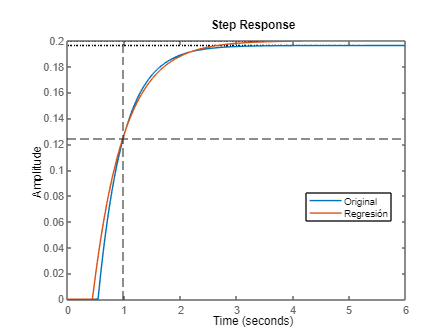

figure(1)
clf
step(G1,6)
hold on
step(g_est1)
yline(k*0.632,'--')
xline(T1+tau1, '--')
legend({'Original','Regresión'},'Location','best')

[yest, test]= step(g_est1,6);
[yreal, treal]= step(G1,6);
gap= yreal(end)-yest(end)

gap = -0.0036

num= [0.524 0.524*0.323];
dem= [1 -0.776 0.125895 0];
g2= tf(num,dem,1) %funcion de transferencia

g2 =
 
       0.524 z + 0.1693
  --------------------------
  z^3 - 0.776 z^2 + 0.1259 z
 
Sample time: 1 seconds
Discrete-time transfer function.



L= 7; %longitud de la secuencia de ponderación 
delay = length(den)-length(num) %cálculo orden de retardo

delay = 2

secuencia= ldiv([0.524 0.524*0.323],[1 -0.776 0.125895 0],L-delay);
secuencia= [zeros(1,delay) secuencia]

secuencia =          0         0    0.5240    0.5759    0.3809    0.2231    0.1252


clf
figure(2)
impulse(g2, 0:1:L-1); %respuesta impulso MATLAB
hold on 
stem(0:1:L-1,secuencia,'r')
grid on 
legend({'Impulso','Secuencia de ponderación'})
clear;clc;close all
N=195;%número de muestras
M=7;%Longitud secuencia de ponderación
noise=0.1;%amplitud del ruido

u=2*(prbs(5,N,[1 0 1 0 0])-0.5);%señal prbs de N datos con valores entre -1 y 1

'prbs' requires SerDes Toolbox.

xdata=0:1:N-1;%instantes de muestreo
[y,t]=lsim(g2,u,xdata);%simulación del modelo con la entrada diseñada
y=y+noise*rand(length(y),1);%adición del ruido a la entrada

[cyu,lagsyu] = xcorr(y,u,M-1);%M elementos de la correlación entre y y u
[cu,lagsu] = xcorr(u,0);%correlación de la entrada con ella misma en el instante 0
tf_est=cyu(lagsyu>=0)./(N:-1:N-M+1)'/(cu/N);%fórmula para la secuencia de ponderación
delay=length(den)-length(num);%cálculo del retardo del sistema
figure(30)
clf
stem(lagsyu,cyu)%gráfica de la correlación de y y u
title('R_{yu}(\tau)')

%Por el método de correlación 
pdata=0:1:M-1;
figure(31)
clf
subplot(2,1,1)
stem(pdata,tf_est)%secuencia estimada
title('Estimado')
subplot(2,1,2)
stem(pdata,secuencia)%secuencia real
title('Real')

%Por funciones de matlab
data = iddata(y,u');%datos para usar las funciones mejoradas de MatLab
sys = impulseest(data,M);%secuencia de ponderación estimada por MatLab
figure(4)
clf
subplot(2,1,1)
h = impulseplot(sys);%secuencia de ponderación estimada por MatLab
subplot(2,1,2)
stem(pdata,secuencia)%secuencia real
title('Real')